# 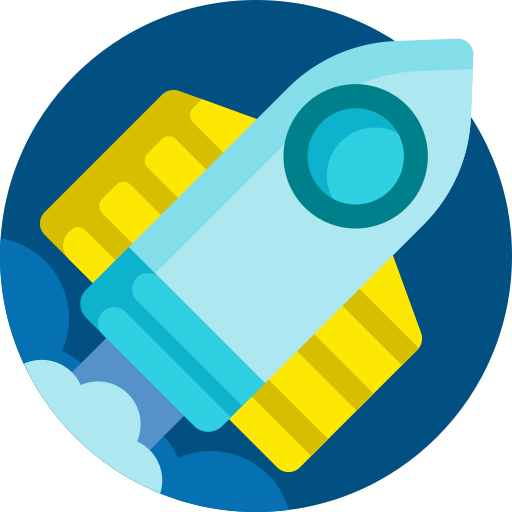

# **MEC3079S: Control Systems**

# Chapter 4 - Modelling in the Laplace domain

## 4.1 Introduction

This chapter will begin by considering the Laplace transform of common signals that we will work with throughout this course. This will hopefully solidify the relationship between time-domain and Laplace-domain signals, and their various properties. Following this, we will look at methods of modelling elementary, single-degree-of-freedom electrical and mechanical systems.

## 4.2 Common Laplace transforms 

Recall that the Laplace transform is defined as

    $F(s) = \mathcal{L}\{f(t)\} =\int_{0-}^{\infty} f(t) e^{-st} \ dt$,

and the corresponding inverse Laplace transform is

$f(t) = \mathcal{L}^{-1} \{ F(s) \}=\frac{1}{2\pi j}\oint_{c}F(s)e^{st}ds$.

Note that the resulting $f(t)$ is defined to be one-sided: $f(t)=0, \forall t<0$. The relationship above requires complex integration, but we can use a Laplace transform table if the transform already exists. The Table below shows the time- and Laplace-domain relationship for a representative sample of common (but by no means exhaustive!) functions:


$$\left.
\begin{array}{lll}
\textbf{Name} & {\bf f(t)} & {\bf F(s)}
\\
\text{Impulse function} \quad& a\delta(t) \quad & a
\\
\text{Step function} \quad& a \quad & \frac{a}{s}
\\
\text{Ramp function} \quad& at \quad & \frac{a}{s^2}
\\
\text{Parabolic function} \quad& \frac{1}{2}at^2 \quad & \frac{a}{s^3}
\\
\text{$n^{th}$-order function} \quad& \frac{1}{n!}at^{n} \quad & \frac{a}{s^{n+1}}
\\
\text{Exponential decay} \quad& ae^{-bt} \quad & \frac{a}{s+b}
\\
\text{Sinusoid} \quad &  a\sin(\omega t) & \frac{a\omega}{s^2+\omega^2}
\\
\text{Cosinusoid} \quad &  a\cos(\omega t)& \frac{as}{s^2+\omega^2}
\end{array}
\right.
$$


Importantly, the table above assumes that $f(t)=0$ for all negative time ($t<0$). Otherwise the relationships above will not hold. As we will see later in the course, this assumption is not an issue in real-world systems that only respond once perturbed (a soccer ball will only begin to move after we have applied a force from our foot). Note also that based on the **homogeneous property**, scalar $a$ does not affect the Laplace transforms in the table above: $\mathcal{L}\{af(t)\}=a\mathcal{L}\{f(t)\}=aF(s)$. 

### 4.2.1 Impulse function

The **impulse function** is defined by the Dirac delta function, $\delta(t)$, which is a signal that is zero everywhere except at $t=0$, where it has a value of infinity


$$f(t)=\delta(t) =\left\{
        \begin{array}{ll}
           \infty, &  t = 0, \\
           0, & t \neq 0. \\
        \end{array}
    \right.$$


The impulse signal has a special property that the time integral over all time is equal to one

$\int_{-\infty}^\infty \delta(t)dt=1$.

By extension, the corresponding Laplace transform follows as


$$\begin{array}{ll}
F(s) &= \int_{0}^{\infty} f(t) e^{-st} \ dt, \\
 &= \int_0^\infty \delta(t) e^{-st}dt, \\
&=1.
\end{array}$$


We can visualise the impulse response using the code below.

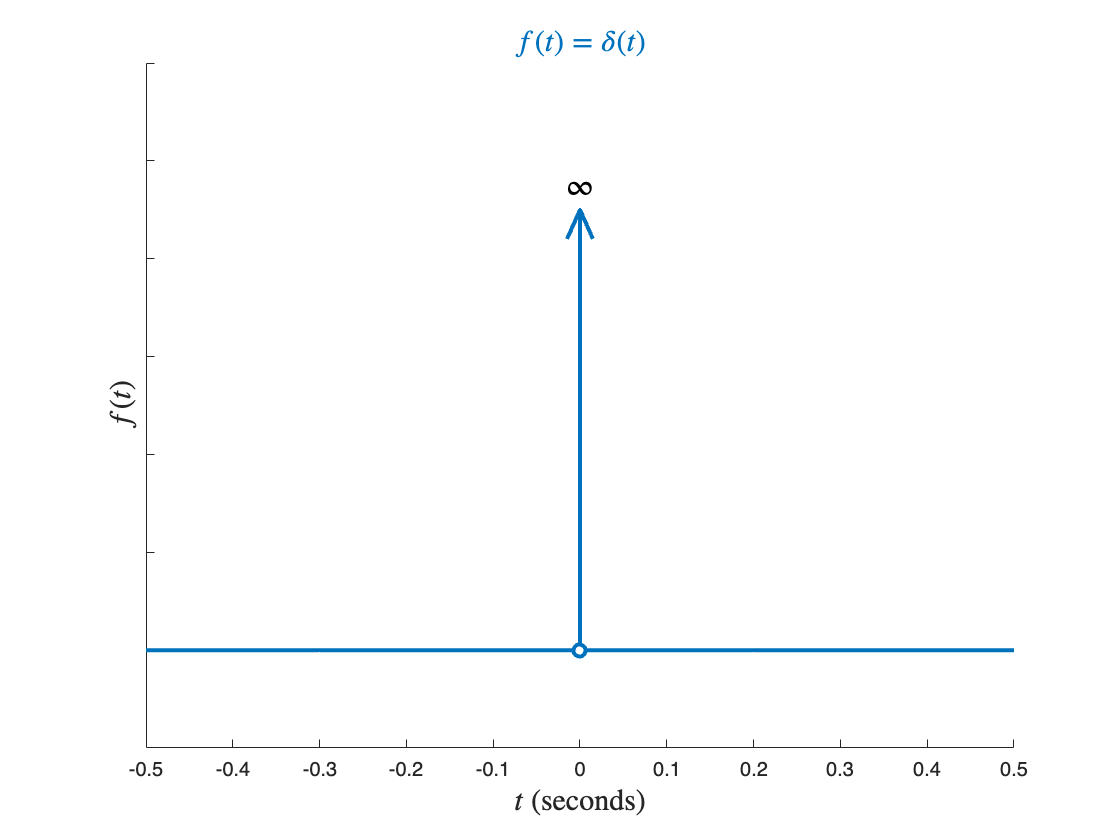

clear
t = -0.5:0.1:0.5;
f = zeros( length(t) );
figure,clf,hold on
plot(t,f,LineWidth=2,Color='#0072BD')
% plot([0 0],[0 1],'b',LineWidth=2)
% plot(0,1,"^")
quiver(0,0,0,1,LineWidth=2,Color='#0072BD')
plot(0,0,'o',LineWidth=2,Color='#0072BD',MarkerFaceColor='white')
set(gca,'yticklabel',[])

xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$f(t)$',Interpreter='latex',FontSize=15)
title('$f(t)=\delta(t)$',Interpreter='latex',FontSize=15,Color='#0072BD')
text(0,0.95,'$\infty$',Interpreter='latex',FontSize=15,HorizontalAlignment='center')
ylim([-0.2 1.2])

### 4.2.2 Step function

The **step function**, often also referred to as the Heaviside step function (`MATLAB` uses this term), is defined in the time-domain as


$$f(t)=\left\{
        \begin{array}{ll}
           a, &  t \geq 0, \\
           0, & t < 0. \\
        \end{array}
    \right.$$


where $a\in \mathbb{R}$ represents the magnitude and direction of the step signal. You can imagine this signal as instantaneously changing from a value of $0$ to $a$ at $t=0$ seconds, and then remaining at a value of $a$ indefinitely. Using our definition of the Laplace transform, the corresponding representation in the Laplace domain is 


$$\begin{array}{ll}
F(s) &= \int_{0}^{\infty} f(t) e^{-st} \ dt, \\
 &= \int_0^\infty ae^{-st}dt, \\
&=\frac{a}{s}.
\end{array}$$


clear
syms s t 

a = 3   %final value of step function

a = 3

y(t) = a*heaviside(t)

$$y(t) = 3\,\mathrm{heaviside}\left(t\right)$$

Y(s) = laplace(y(t))

$$Y(s) = \frac{3}{s}$$

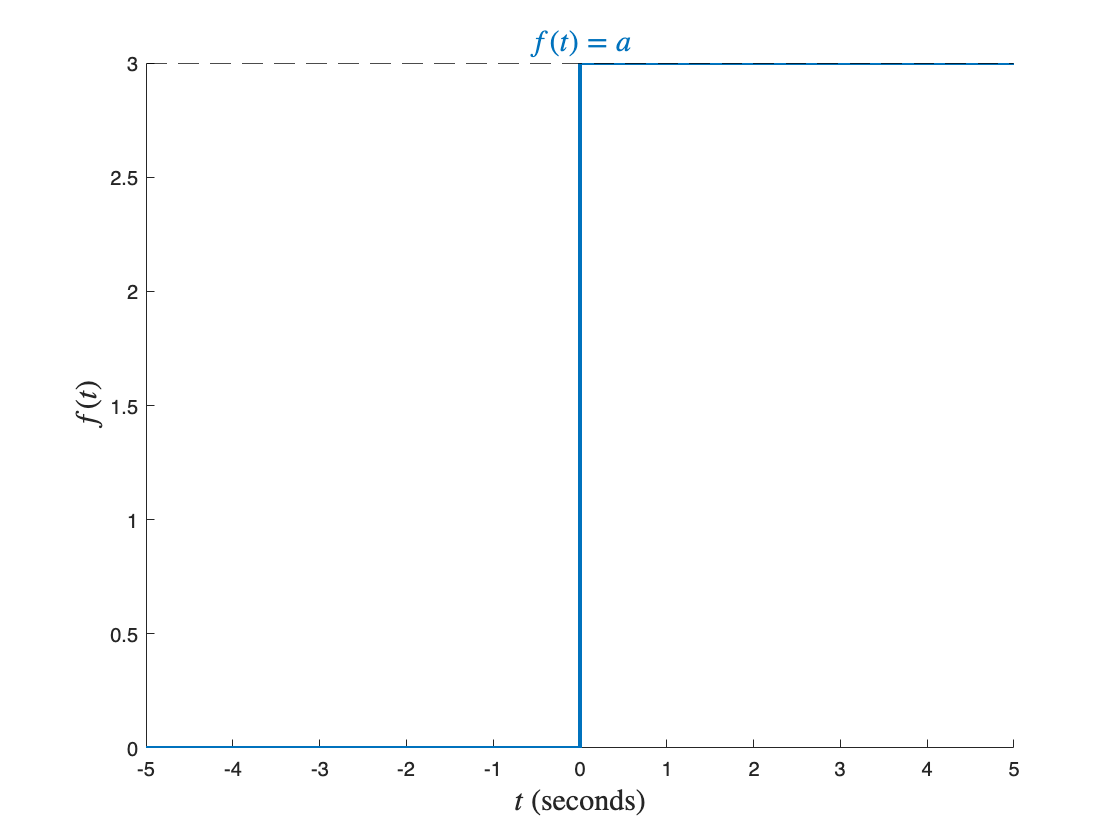

figure,hold on
fplot(y(t),LineWidth=2)
yline(a,'--k',['a=',num2str(a)],FontSize=15)
xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$f(t)$',Interpreter='latex',FontSize=15)
title('$f(t)=a$',Interpreter='latex',FontSize=15,Color='#0072BD')

### 4.2.3 Ramp function

The **ramp function**, with slope $a$, is defined as


$$f(t)=\left\{
        \begin{array}{ll}
           at, &  t \geq 0, \\
           0, & t < 0. \\
        \end{array}
    \right.$$


The corresponding Laplace transform is 


$$\begin{array}{ll}
F(s) &= \int_{0}^{\infty} f(t) e^{-st} \ dt, \\
 &= \int_0^\infty ate^{-st}dt, \\
&=\frac{a}{s^2}.
\end{array}$$


clear
syms s t 

a = -2  %gradient (velocity) of ramp function

a = -2

y(t) = a*heaviside(t)*t

$$y(t) = -2\,t\,\mathrm{heaviside}\left(t\right)$$

Y(s) = laplace(y(t))

$$Y(s) = -\frac{2}{s^{2}}$$

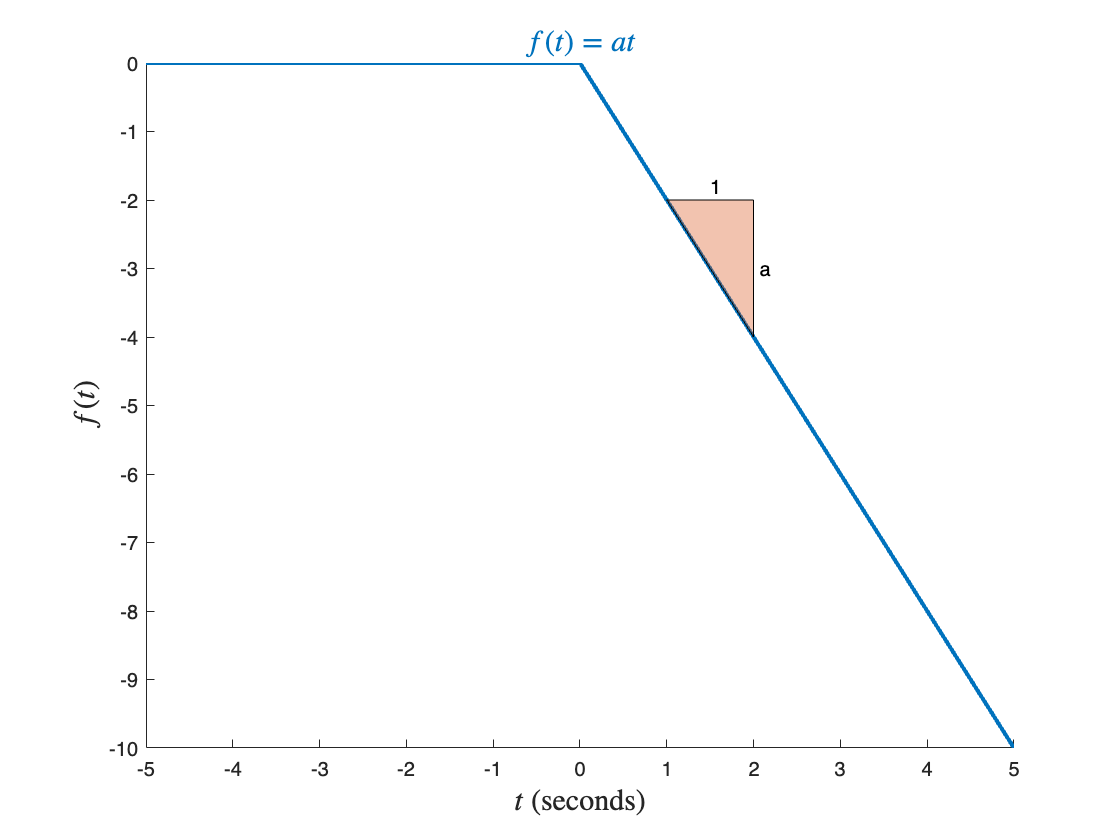

figure,hold on
fplot(y(t),LineWidth=2)
xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$f(t)$',Interpreter='latex',FontSize=15)
title('$f(t)=at$',Interpreter='latex',FontSize=15,Color='#0072BD')
p = polyshape([1 2 2],[a a 2*a]);
plot(p),text(2,1.5*a,' a'),text(1.5,.9*a,'1')

### 4.2.4 Parabolic function

The **parabolic function** is defined as


$$f(t)=\left\{
        \begin{array}{ll}
           \frac{1}{2}at^2, &  t \geq 0, \\
           0, & t < 0. \\
        \end{array}
    \right.$$


The corresponding Laplace transform is 


$$\begin{array}{ll}
F(s) &= \int_{0}^{\infty} f(t) e^{-st} \ dt, \\
 &= \int_0^\infty \frac{1}{2}at^2e^{-st}dt, \\
&=\frac{a}{s^3}.
\end{array}$$


clear
syms s t 

a = -1; %acceleration of f(t)

y(t) = a*heaviside(t)*t^2/2

$$y(t) = -\frac{t^{2}\,\mathrm{heaviside}\left(t\right)}{2}$$

Y(s) = laplace(y(t))

$$Y(s) = -\frac{1}{s^{3}}$$

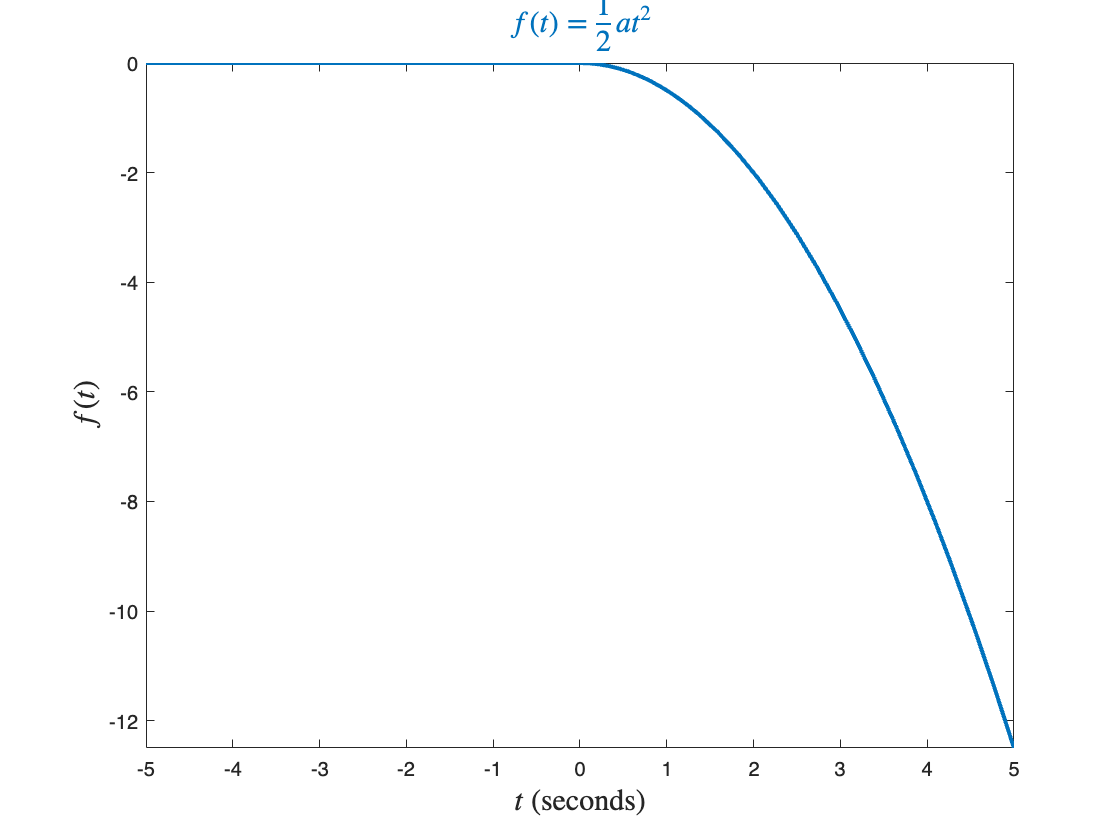

figure
fplot(y(t),LineWidth=2)
xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$f(t)$',Interpreter='latex',FontSize=15)
title('$f(t)=\frac{1}{2}at^2$',Interpreter='latex',FontSize=15,Color='#0072BD')

### 4.2.5 Exponential function

The **exponential function** is defined by


$$f(t)=\left\{
        \begin{array}{ll}
           ae^{-bt}, &  t \geq 0, \\
           0, & t < 0. \\
        \end{array}
    \right.$$


The description of the signal in the Laplace domain follows as


$$\begin{array}{ll}
F(s) &= \int_{0}^{\infty} f(t) e^{-st} \ dt, \\
 &= a\int_0^\infty e^{-bt}e^{-st}dt, \\
&=\frac{a}{s+b}.
\end{array}$$


Parameter $a$ defines the value of $f(0)$, based on $f(0)=\lim_{t\rightarrow 0}{ae^{-bt}}=a$. Value $b$ dictates the rate of convergence (towards zero) or divergence (towards infinity) of $f(t)$. Note that $f(t)$ tends to zero if $b>0$ and tends to infinity if $b<0$:


$$\lim_{t\rightarrow \infty}f(t)=\left\{
        \begin{array}{ll}
          0, &  b > 0, \\
          a, &  b = 0, \\
           \infty, & b < 0. \\
        \end{array}
    \right.$$


clear
syms s t 

a = -6;
b = 7;

y(t) = a*heaviside(t)*exp(-b*t)

$$y(t) = -6\,{\mathrm{e}}^{-7\,t}\,\mathrm{heaviside}\left(t\right)$$

Y(s) = laplace(y(t))

$$Y(s) = -\frac{6}{s+7}$$

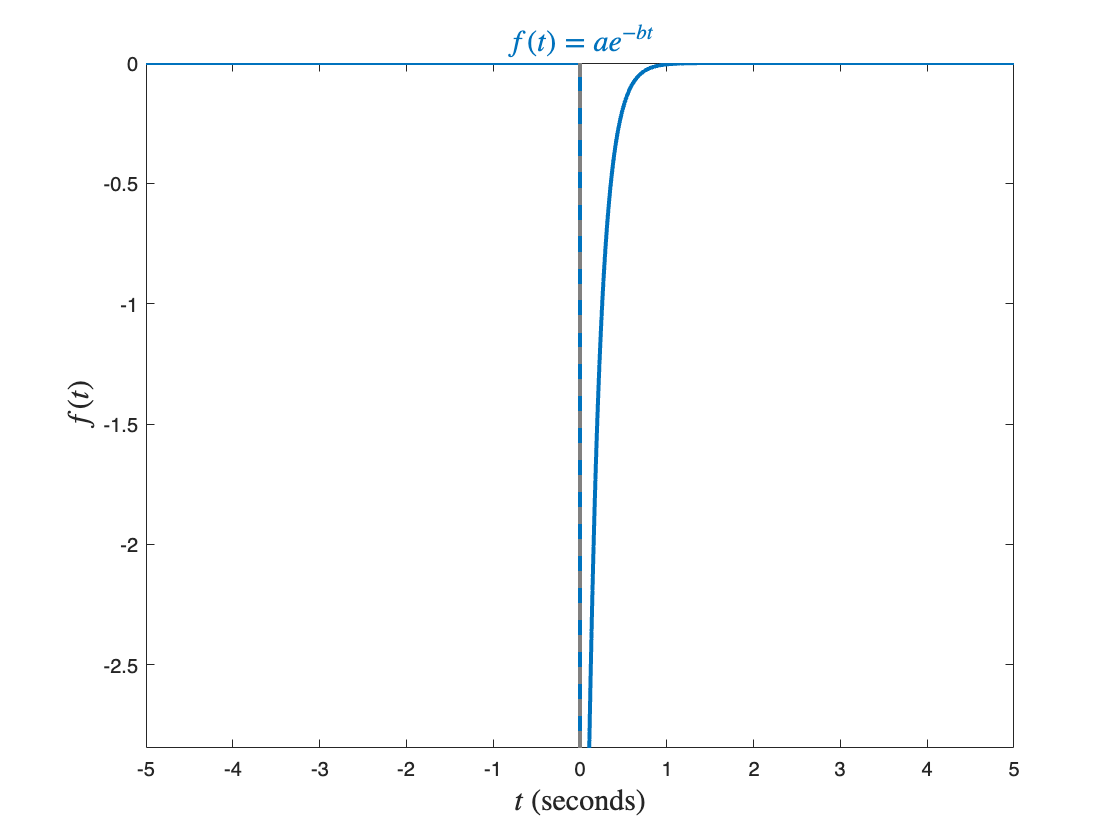

figure
fplot(y(t),LineWidth=2)
xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$f(t)$',Interpreter='latex',FontSize=15)
title('$f(t)=ae^{-bt}$',Interpreter='latex',FontSize=15,Color='#0072BD')

### 4.2.6 Sinusoidal function

The one-sided **sinusoidal **function, with amplitude $|a|$, is defined by


$$f(t)=\left\{
        \begin{array}{ll}
           a\sin(\omega t), &  t \geq 0, \\
           0, & t < 0. \\
        \end{array}
    \right.$$


The description of the signal in the Laplace domain follows as


$$F(s)= a\frac{\omega}{s^2+\omega^2}.
$$


clear
syms s t 

a = -5;
w = 9;

y(t) = a*heaviside(t)*sin(w*t)

$$y(t) = -5\,\sin\left(9\,t\right)\,\mathrm{heaviside}\left(t\right)$$

Y(s) = laplace(y(t))

$$Y(s) = -\frac{45}{s^{2}+81}$$

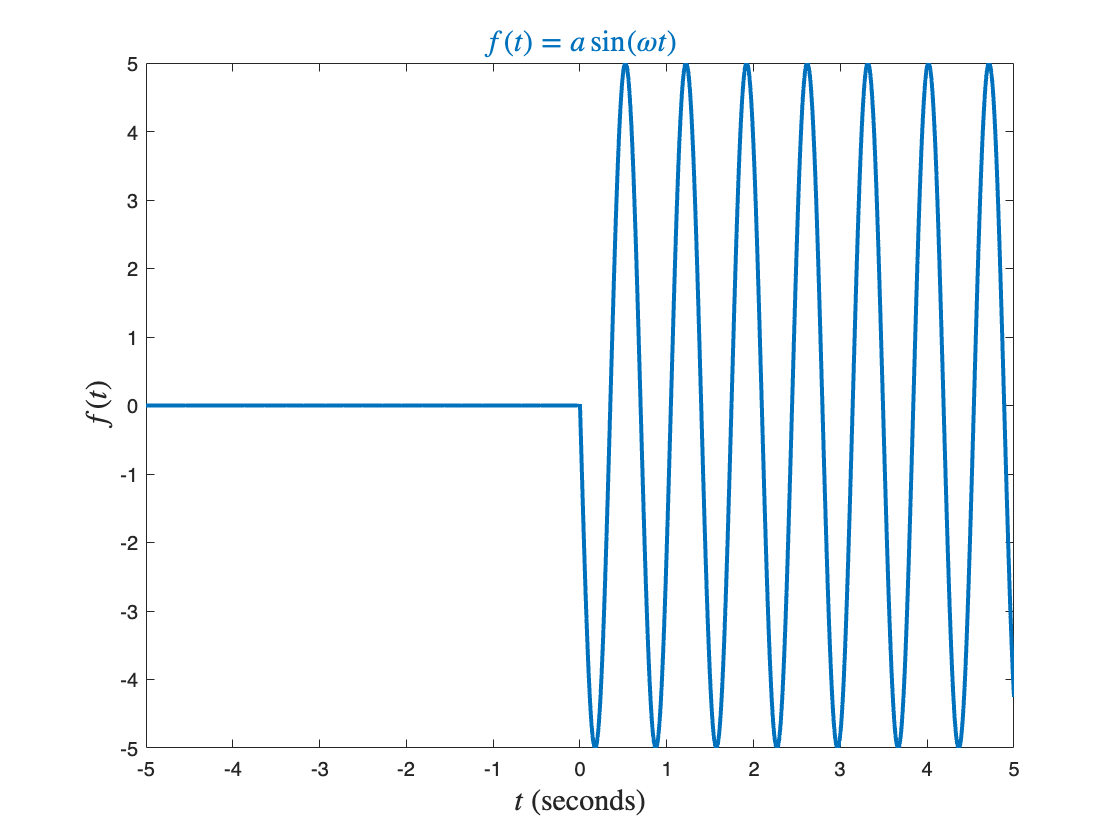

figure
fplot(y(t),LineWidth=2)
xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$f(t)$',Interpreter='latex',FontSize=15)
title('$f(t)=a\sin(\omega t)$',Interpreter='latex',FontSize=15,Color='#0072BD')

### 4.2.7 Cosinusoidal function

The one-sided **cosinusoidal **function, with amplitude $|a|$, is defined by


$$f(t)=\left\{
        \begin{array}{ll}
           a\cos(\omega t), &  t \geq 0, \\
           0, & t < 0. \\
        \end{array}
    \right.$$


The description of the signal in the Laplace domain follows as


$$F(s)= a\frac{s}{s^2+\omega^2}.
$$


clear
syms s t 

a = 2;
w = 5;

y(t) = a*heaviside(t)*cos(w*t)

$$y(t) = 2\,\cos\left(5\,t\right)\,\mathrm{heaviside}\left(t\right)$$

Y(s) = laplace(y(t))

$$Y(s) = \frac{2\,s}{s^{2}+25}$$

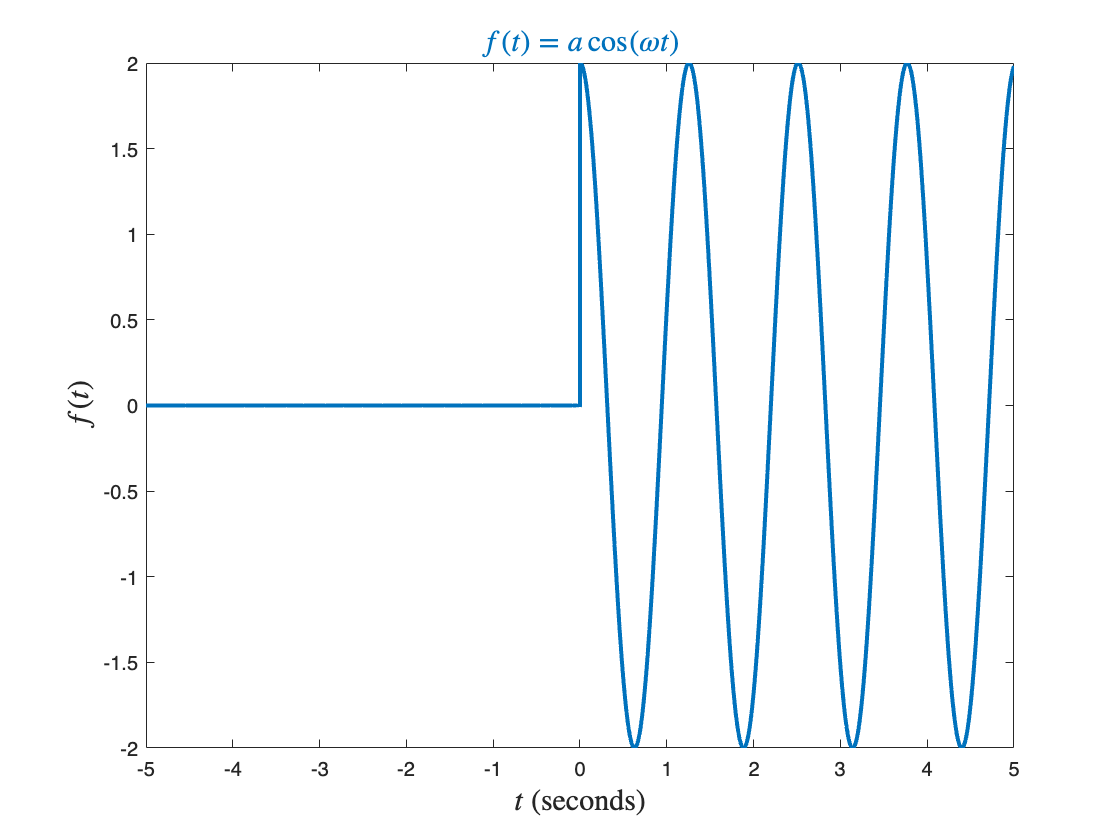

figure
fplot(y(t),LineWidth=2)
xlabel('$t$ (seconds)',Interpreter='latex',FontSize=15)
ylabel('$f(t)$',Interpreter='latex',FontSize=15)
title('$f(t)=a\cos(\omega t)$',Interpreter='latex',FontSize=15,Color='#0072BD')

### 4.2.8 Integration and differentiation

As previously shown, the Laplace transform of the $k^{th}$ derivative of $f(t)$ is given as


$$
\mathcal{L}\{\frac{d^k}{dt^k}f(t)\}=s^kF(s)

$$


when all initial conditions are set to zero. Reflecting on our Laplace transform table, repeated below in Table 4.1 for sake of convenience, we can make use of the equation above to "move up" the table of functions in the following order: 

parabolic function -> ramp function -> step function -> impulse function. 

**Table 4.1:** Laplace transform table.


$$\left.
\begin{array}{lll}
\textbf{Name} & {\bf f(t)} & {\bf F(s)}
\\
\text{Impulse function} \quad& \delta(t) \quad & 1
\\
\text{Step function} \quad& a \quad & \frac{a}{s}
\\
\text{Ramp function} \quad& at \quad & \frac{a}{s^2}
\\
\text{Parabolic function} \quad& \frac{1}{2}at^2 \quad & \frac{a}{s^3}
\\
\text{$n^{th}$-order function} \quad& \frac{1}{n!}at^{n} \quad & \frac{a}{s^{n+1}}
\\
\text{Exponential decay} \quad& ae^{-bt} \quad & \frac{a}{s+b}
\\
\text{Sinusoid} \quad &  a\sin(\omega t) & \frac{a\omega}{s^2+\omega^2}
\\
\text{Cosinusoid} \quad &  a\cos(\omega t)& \frac{as}{s^2+\omega^2}
\end{array}
\right.
$$


For example, the ramp function has a Laplace transform of $\frac{a}{s^2}$ and when we multiply this by an $"s"$ term (representing differentiation), we get $\frac{a}{s}$, which represents a step function (or the gradient of the ramp function). 

Recall also that the Laplace transform of the time integral of signal $f(t)$ is given as

 $\mathcal{L}\{\int_0^t f(\tau) d\tau\}=  \frac{F(s)}{s}$.

If we wanted to visualise the integral of the step function, $\frac{a}{s}$, all we need to do is multiply that signal (in the Laplace domain) by $\frac{1}{s}$ (representing an integration operation), which gives us $\frac{a}{s^2}$ — the ramp signal that represents the integration of the step signal.

Consulting the sinusoid and co-sinusoid entries in the table, we also know that

$\frac{d}{dt}\{a\sin(\omega t)\}=a\frac{d}{dt}\{\sin(\omega t)\}=a\omega\cos(\omega t)$.

It follows that

$\mathcal{L}\{\frac{d}{dt}\{a\sin(\omega t)\}\}=\mathcal{L}\{a\omega\cos(\omega t)\}=\frac{a\omega s}{s^2+\omega^2}=s\mathcal{L}\{a\sin(\omega t)\}$.

## 4.3 Modelling electrical systems

We can use our understanding of Laplace transform properties to model the behaviour of resistors, inductors, and capacitors in the Laplace domain.

### 4.3.1 Modelling the impedance of electrical components

#### Resistor

The voltage across a resistor, $v_R(t)$, is modelled as

$v_R(t)=Ri(t)$,

where $R$ is the resistance, measured in Ohms, and $i(t)$ is the current passing through the resistor. 

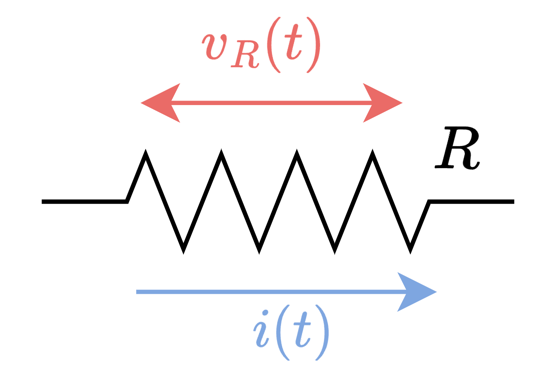

**Figure 4.1:** Resistor with voltage across it.

The corresponding Laplace transform is

$V_R(s)=\mathcal{L}\{ Ri(t)\}=RI(s)$.

#### Inductor

The voltage across an inductor, $v_L(t)$, is modelled as

$v_L(t)=L\frac{di(t)}{dt}$,

where $L$ is the inductance, measured in Henries, and $i(t)$ is the current passing through the inductor. 

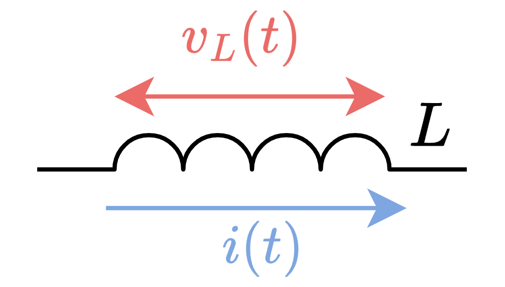

**Figure 4.2:** Inductor with voltage across it.

The corresponding Laplace transform is

$V_L(s)=\mathcal{L}\{ L\frac{di(t)}{dt}\}=LsI(s)$.

#### Capacitor

The voltage across a capacitor, $v_C(t)$, is modelled as

$v_C(t)=\frac{1}{C}\int_{0}^{t}i(\tau)d\tau$,

where $C$ is the inductance, measured in Farads, and $i(t)$ is the current passing through the capacitor. 

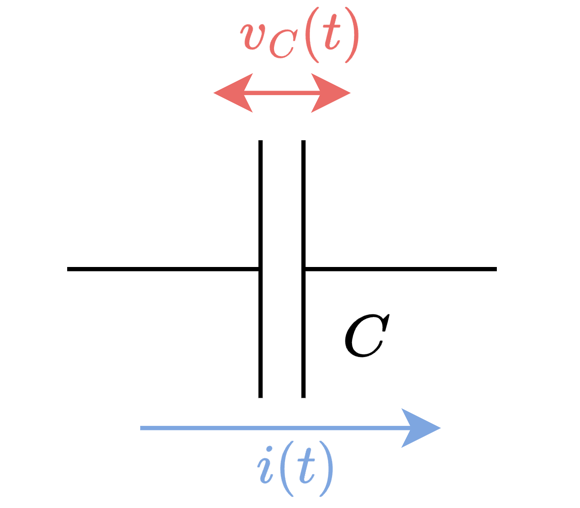

**Figure 4.3:** Capacitor with voltage across it.

The corresponding Laplace transform is

$V_C(s)=\mathcal{L}\{ \frac{1}{C}\int_{0}^{t}i(\tau)d\tau\}=\frac{1}{Cs}I(s)$.

#### Summary of impedances

The electrical components and their important inter-relationships are summarised in the table below.

**Table 4.2:** Summary of capacitor, resistor, and inductor relationships.

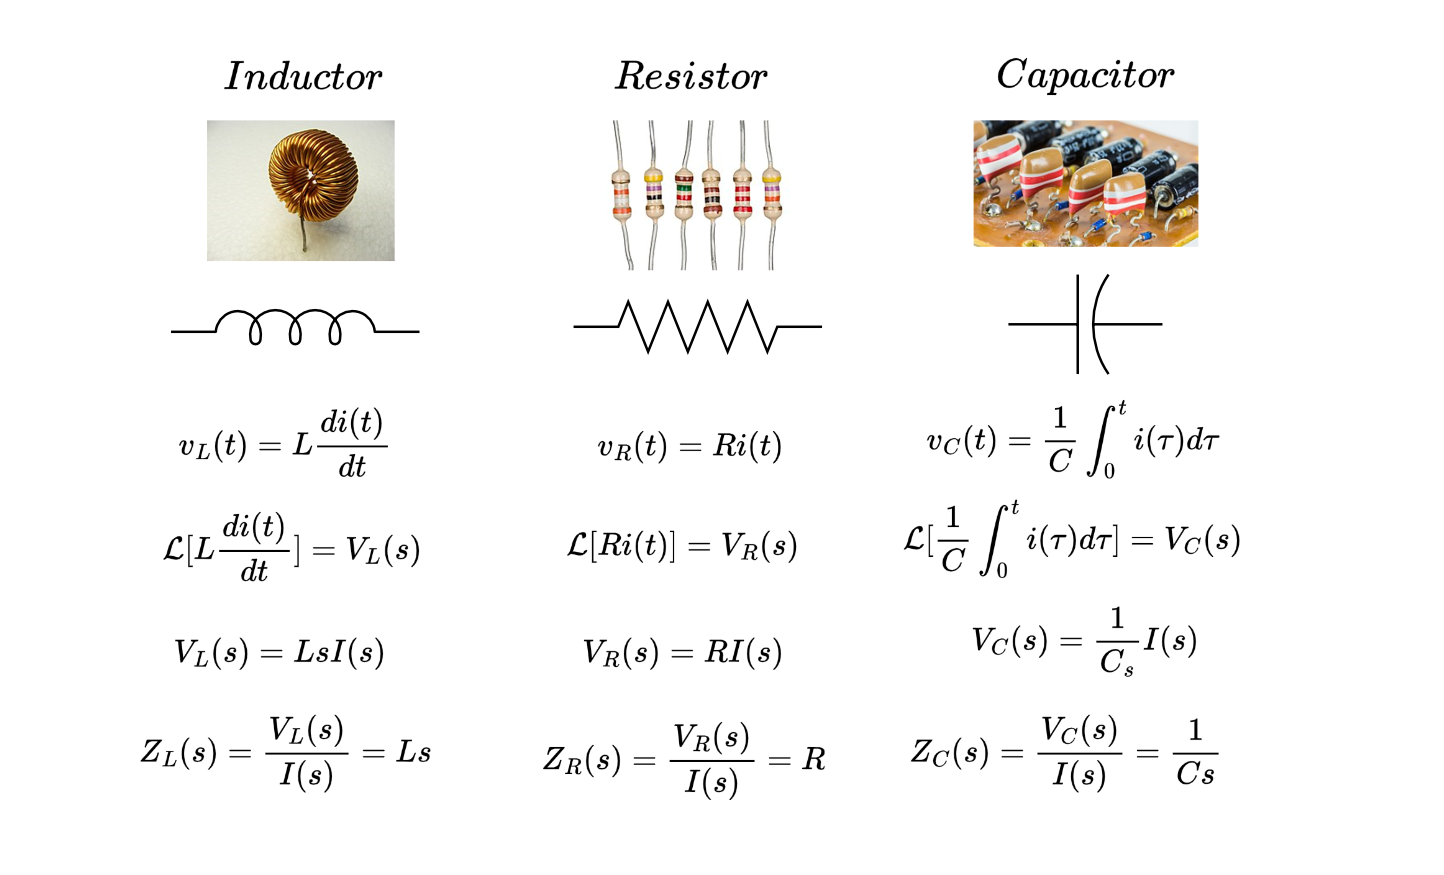

### 4.3.2 Simple circuits via mesh analysis

**Mesh analysis **uses Kirchoff's voltage law (KVL) to sum voltages around current loops. We can then construct a governing differential equation, followed by applying the Laplace transform (assuming zero initial conditions) and then determining the transfer function relationship of interest.

Consider the RLC circuit below.

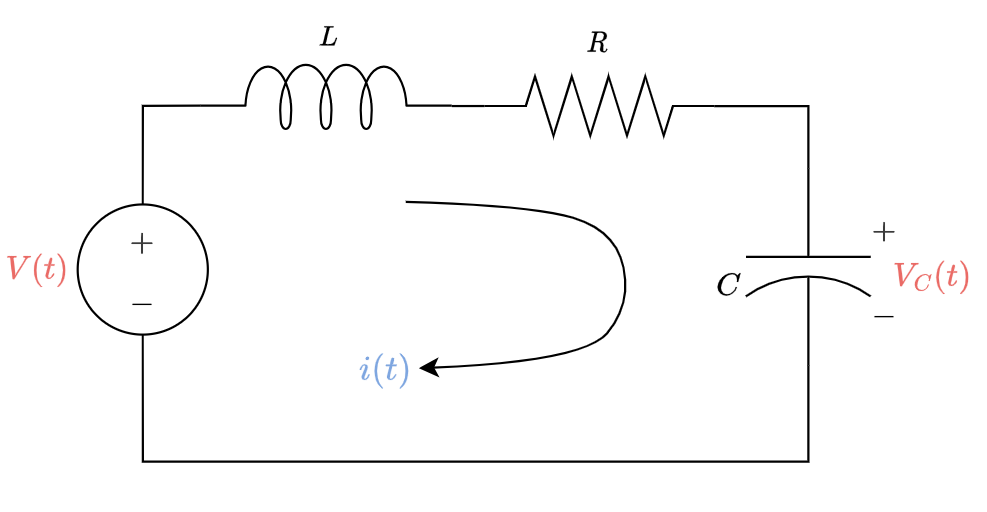

**Figure 4.4:** RLC circuit.

From the circuit above, and using the Table above, the corresponding differential equation after summing all voltages is


$$\begin{array}{rl}
v(t)
&=v_L(t)+v_R(t)+v_C(t), \\
&=L\frac{d}{dt}i(t)+Ri(t)+\frac{1}{C}\int_0^ti(\tau)d\tau. \\
\end{array}$$


Applying the Laplace transform yields

$\begin{array}{rl}
V(s)
&=LsI(s)+RI(s)+\frac{1}{Cs}I(s)\\
&=\left[Ls+R+\frac{1}{Cs}\right]I(s)\\
\end{array}$.

The current then depends on the input voltage via

$\frac{I(s)}{V(s)}=\frac{1}{Ls+R+\frac{1}{Cs}}$.

The voltage over the capacitor is $V_C(s)=\frac{1}{Cs}I(s)$, which gives

$\frac{V_c(s)}{V(s)}=\frac{\frac{1}{Cs}}{Ls+R+\frac{1}{Cs}}=\frac{\frac{1}{LC}}{s^2+\frac{R}{L}s+\frac{1}{LC}}$.

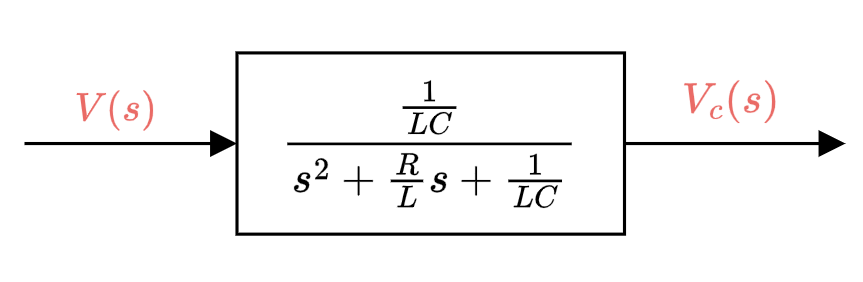

**Figure 4.5:** Block diagram of RLC circuit.

Note that once we determine the relationship between the input voltage and the circuit current, it is then very easy to determine the voltage across any one component.

### 4.3.3 The transform method

Each component has an associated impedance, $Z$, which can be thought of as a (potentially) dynamic resistance. The impedance of each component is determined by finding the ratio of the voltage across the component and the current through the component ($V(s)/I(s)$). The table below summarised the three impedances.

**Table 4.3:** Summary of impedances.


$$\left.
\begin{array}{ccc}
\textbf{Component} \quad& \textbf{Ratio} \quad& \textbf{Impedance}
\\
\text{Resistor} \quad& \frac{V_R(s)}{I(s)} \quad & Z_R(s)=R
\\
\text{Inductor} \quad& \frac{V_L(s)}{I(s)} \quad & Z_L(s)=Ls
\\
\text{Capacitor} \quad& \frac{V_C(s)}{I(s)} \quad & Z_C(s)=\frac{1}{Cs}
\\
\end{array}
\right.
$$


For any current loop, the components will collectively make up a summed impedance that when scaled with the current gives the voltage applied to the loop.

$\sum_{k=1}^n Z_k(s) I(s) = \sum_{k=1}^n V_k(s)$.

We can use this approach to replace each component in a network with their impedance. We can then use the relationship above to relate current to voltage, thereby determining any transfer function relationship of interest. The left-hand figure below shows the original circuit, and the right-hand figure shows the transformed circuit.

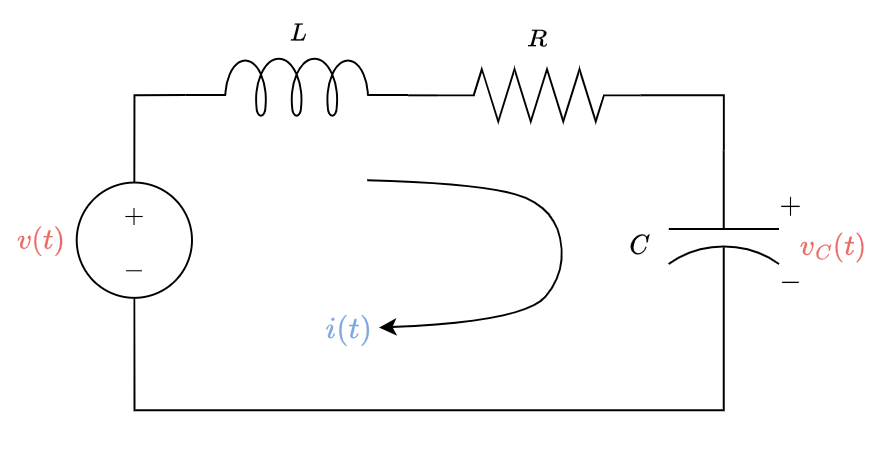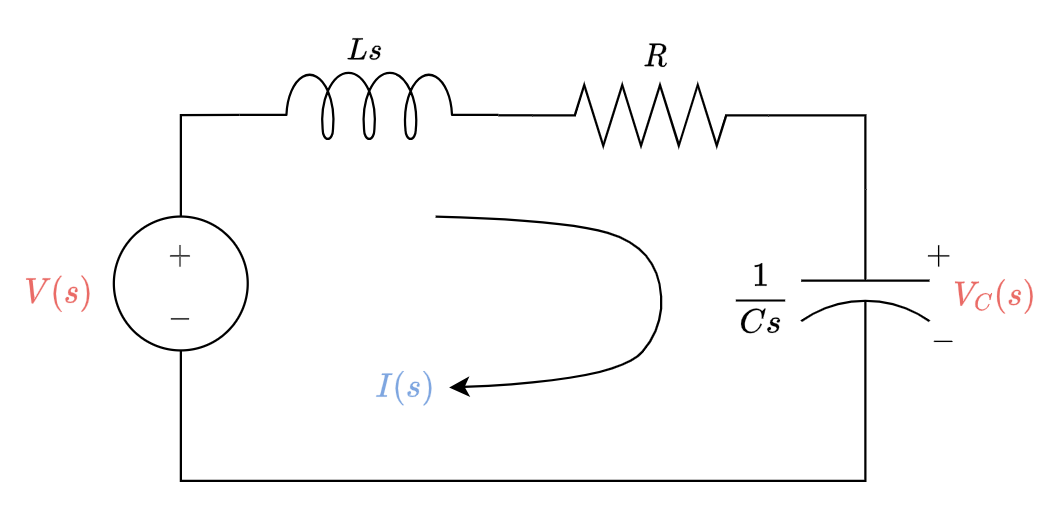

**Figure 4.6:** Original RLC circuit (left) and transformed circuit (right).

Using the relationship above,


$$\begin{array}{ll}
V(s) 
&=\left[Z_L(s)+Z_R(s)+Z_C(s)\right]I(s), \\
&=\left[Ls+R+\frac{1}{Cs}\right]I(s). \\
\end{array}$$


The current then relates to the input voltage via

$\frac{I(s)}{V(s)}=\frac{1}{Ls+R+\frac{1}{Cs}}$.

The voltage over the capacitor is $V_c(s)=\frac{1}{Cs}I(s)$, which gives

$\frac{V_c(s)}{V(s)}=\frac{\frac{1}{Cs}}{Ls+R+\frac{1}{Cs}}=\frac{\frac{1}{LC}}{s^2+\frac{R}{L}s+\frac{1}{LC}}$.

The two methods are equivalent, but the transform approach simplifies the process significantly.

## 4.4 Modelling translational mechanical systems

### 4.4.1 Modelling the impedance of translational mechanical components

Mechanical systems parallel electrical networks to such an extent that there are analogies between electrical and mechanical components and variables. Mechanical systems, like electrical networks, have three passive, linear components. Two of them, the spring and the mass, are energy-storage elements; one of them, the viscous damper, dissipates energy. The two energy-storage elements are analogous to the two electrical energy-storage elements, the inductor and capacitor. The energy dissipator is analogous to electrical resistance.

Analogous to the electrical networks where we considered the voltage across each component, we can consider the force across each translational mechanical component. We can then apply the Laplace transform to determine the mechanical impedance of each component.

#### Mass

An object with mass, when experiencing an acceleration, has a force, $f_M(t)$, which described by

$f_M(t)=M\ddot{x}(t)$,

where $M$ is the mass, measured in kilograms, and $\ddot{x}(t)$ is the acceleration of the mass.

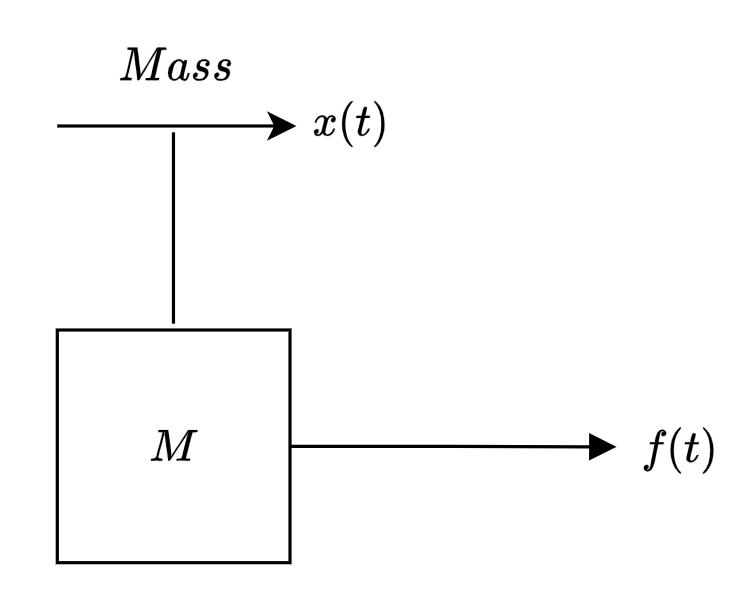

**Figure 4.7:** Mass experiencing a force.

The corresponding Laplace transform is 

$F_M(s)=Ms^2X(s)$.

We can then determine the mechanical impedance of the mass, which is determined by finding the ratio of the force and displacement, namely

$Z_M(s)=\frac{F_M(s)}{X(s)}=Ms^2$.

#### Spring

A spring produces force as a result of displacement from its equilibrium position, which is described by

$f_S(t)=Kx(t)$,

where $K$ is the spring coefficient, measured in Newtons/metre, and $x(t)$ is the relative displacement experienced by the spring.

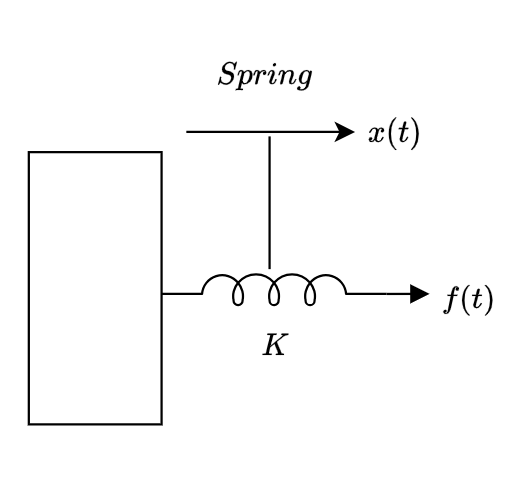

**Figure 4.8:** Spring experiencing a force.

The corresponding Laplace transform is 

$F_S(s)=KX(s)$.

The mechanical impedance of the spring follows as

$Z_S(s)=\frac{F_S(s)}{X(s)}=K$.

#### Viscous damper

A damper (or dashpot) produces an opposing force that is proportional to the linear velocity experienced, which is described by

$f_D(t)=D\dot{x}(t)$,

where $C_v$ is the damping coefficient, measured in Newtons.seconds/metre, and $\dot{x}(t)$ is the relative velocity acting on the damper.

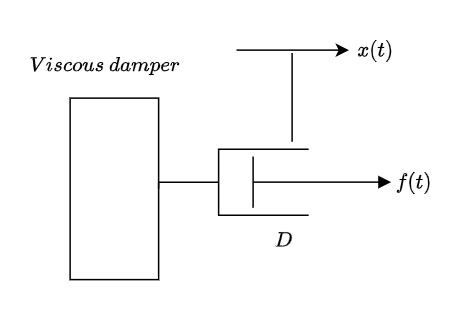

**Figure 4.9:** Viscous damper experiencing a force.

The corresponding Laplace transform is 

$F_D(s)=DsX(s)$.

The mechanical impedance of the damper follows as

$Z_D(s)=\frac{F_D(s)}{X(s)}=Ds$.

#### Summary of impedances

The translational mechanical components and their important inter-relationships are summarised in the table below.

**Table 4.4:** Summary of mechanical components and inter-related properties.

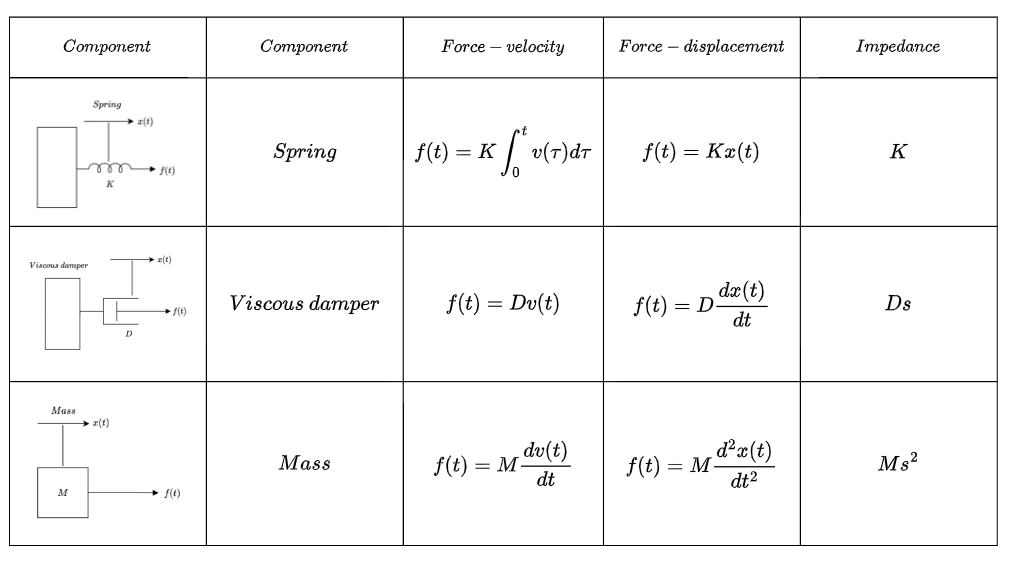

### 4.4.2 Translational mass-spring-damper system

The mass-spring-damper system is shown below.

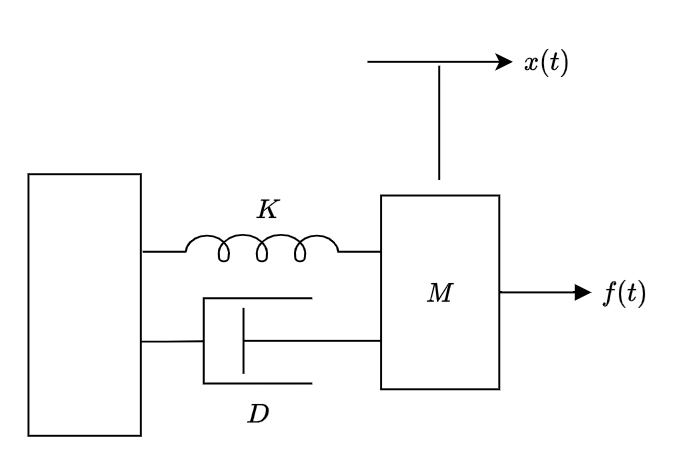

**Figure 4.10:** Mass-spring-damper system experiencing a force.

We start by drawing a free body diagram as shown in the figure below.

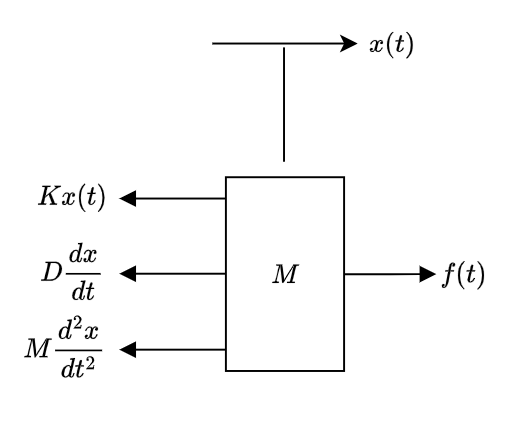

**Figure 4.11:** Free body diagram of mass-spring-damper system experiencing a force.

Balancing the forces, we arrive at the governing differential equation


$$\begin{array}{rl}
f(t)
&=f_S(t)+f_D(t)+f_M(t),\\
&=Kx(t)+D\frac{d}{dt}x(t)+M\frac{d^2}{dt^2}x(t).\\
\end{array}$$


Applying the Laplace transform to the equation above yields


$$\begin{array}{rl}
F(s)
&=F_S(s)+F_D(s)+F_M(s)), \\
&=KX(s)+DsX(s)+Ms^2X(s), \\
&=\left[K+Ds+Ms^2\right]X(s).
\end{array}$$


The transfer function describing the relationship between the applied force and resulting displacement is 

$\frac{X(s)}{F(s)}=\frac{1}{Ms^2+Ds+K}$.

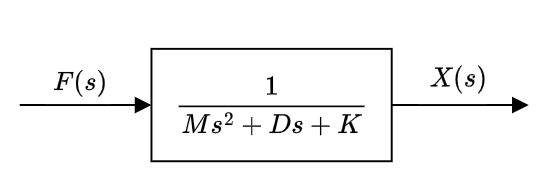

**Figure 4.12:** Block diagram diagram of mass-spring-damper system experiencing a force.

As with the electrical network, we can move straight to the transformed system by replacing the forces with their respective mechanical impedances, as shown in the transformed free body diagram below

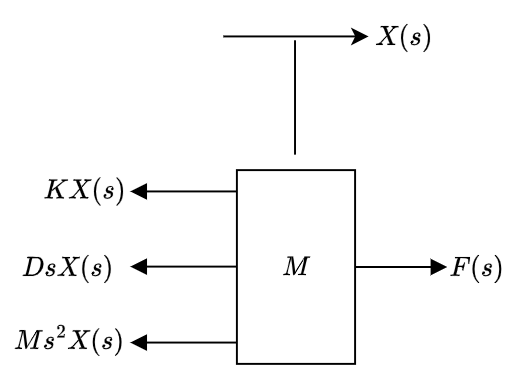

**Figure 4.13:** Transformed free body diagram of mass-spring-damper system experiencing a force.

This allows use to arrive at the same result as before, albeit with less steps. Specifically, if we multiply the sum of all mechanical impedances with the displacement, this will equal the applied forces

$\sum_{k=1}^n Z_k(s) X(s) = \sum_{k=1}^n F_k(s)$.

## 4.5 Modelling rotational mechanical systems

Rotational mechanical systems have identical properties to that of translation mechanical systems, with the only difference being that the components experience rotational motion instead of rectilinear motion.

### 4.5.1 Modelling the impedance of rotational mechanical components

#### Inertia

An object with inertia, when experiencing a rotational acceleration, has a torque, $\tau_J(t)$, which described by

$\tau_J(t)=J\ddot{\theta}(t)$,

where $J$ is the inertia, measured in kilogram.metres$^2$, and $\ddot{\theta}(t)$ is the rotational acceleration of the inertia.

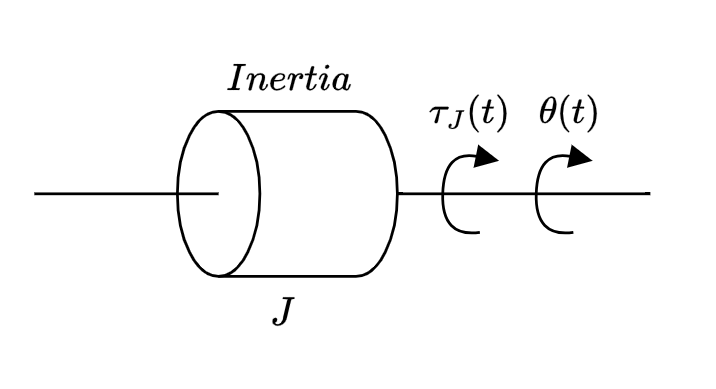

**Figure 4.14:** Object with rotational inertia experiencing a torque.

The corresponding Laplace transform is 

$T_J(s)=Js^2\theta(s)$.

We can then determine the mechanical impedance of the inertia, which is determined by finding the ratio of the torque and rotational displacement, namely

$Z_J(s)=\frac{T_J(s)}{\theta(s)}=Js^2$.

#### Spring

A torsional spring produces torque as a result of rotational displacement from its equilibrium position, which is described by

$\tau_S(t)=K\theta(t)$,

where $K$ is the spring coefficient, measured in Newtons/radian, and $\theta(t)$ is the relative rotational displacement experienced by the spring.

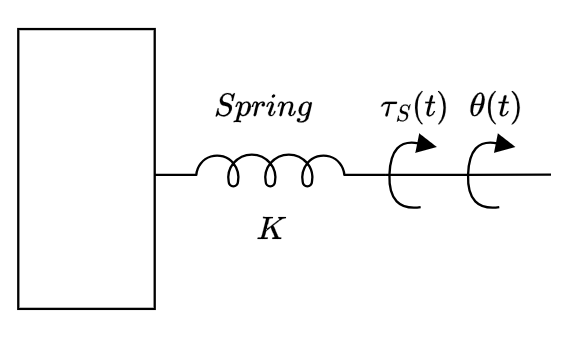

**Figure 4.15:** Torsional spring experiencing a torque.

The corresponding Laplace transform is 

$T_S(s)=K\theta(s)$.

The mechanical impedance of the spring follows as

$Z_S(s)=\frac{T_S(s)}{\theta(s)}=K$.

#### Viscous damper

A torsional damper produces a torque that is proportional to the rotational velocity experienced, which is described by

$\tau_D(t)=D\dot{\theta}(t)$,

where $D$ is the damping coefficient, measured in Newtons.seconds/radian, and $\dot{\theta}(t)$ is the relative rotational velocity acting on the damper.

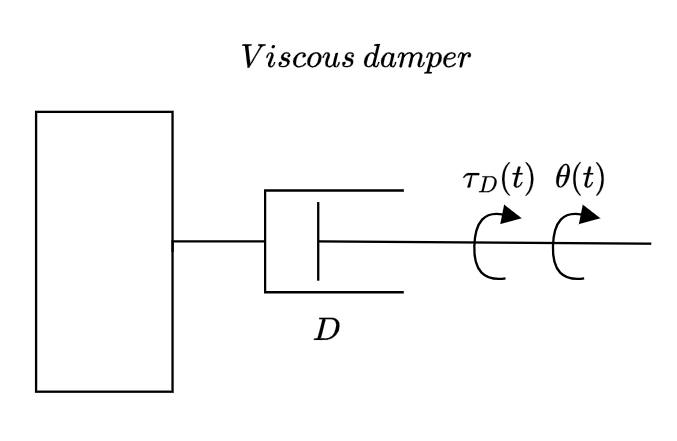

**Figure 4.16:** Viscous damper experiencing a torque.

The corresponding Laplace transform is 

$T_D(s)=DsX(s)$.

The mechanical impedance of the damper follows as

$Z_D(s)=\frac{T_D(s)}{\theta(s)}=Ds$.

#### Summary of impedances

The rotational mechanical components and their important inter-relationships are summarised in the table below.

**Table 4.5:** Summary of rotational mechanical components and inter-related properties.

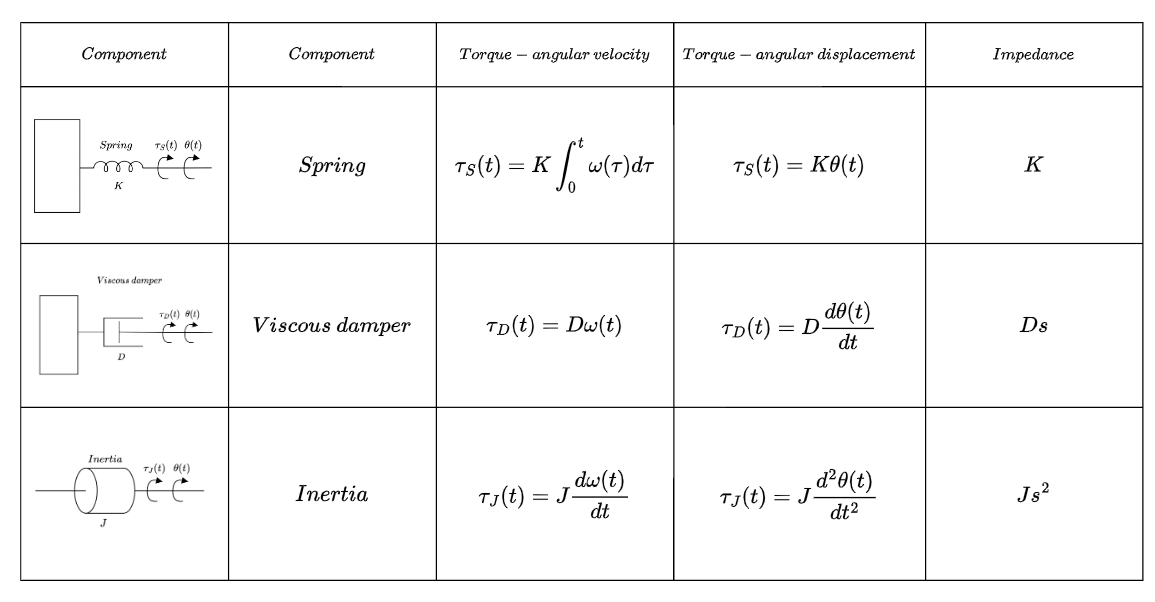

### 4.5.2 Torsional mass-spring-damper system

The torsional mass-spring-damper system is shown below.

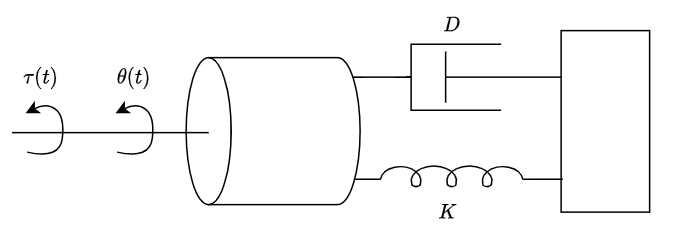

**Figure 4.17:** Torsional mass-spring-damper system experiencing a torque.

As with the translational mechanical system, we can develop the Laplace-transformed torque equation by multiplying the sum all rotational impedances with the rotational displacement, which must equal the sum all applied torques

$\sum_{k=1}^n Z_k(s) \theta(s) = \sum_{k=1}^n T_k(s)$.

The torque equation for the torsional mass-spring-damper system follows as


$$\begin{array}{rl}
T(s)
&=\left[Z_J(s)+Z_D(s)+Z_S(s)\right]\theta(s), \\
&=\left[Js^2+Ds+K\right]\theta(s). \\
\end{array}$$


The transfer function relating the applied torque to the rotational displacement of the inertia is

$\frac{\theta(s)}{T(s)}=\frac{1}{Js^2+Ds+K}$.

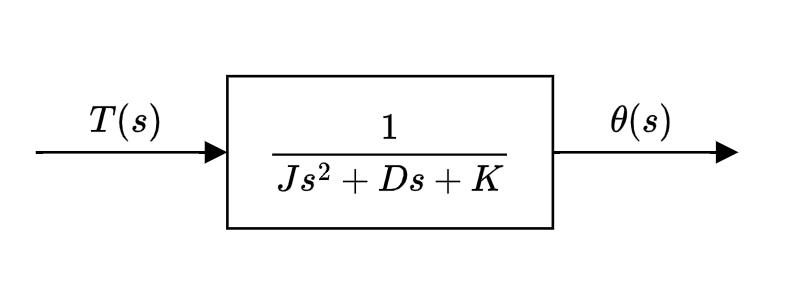

**Figure 4.18:** Block diagram of torsional mass-spring-damper system.

## 4.6 Modelling systems with gears

The mechanical relationship between two idealised, meshed gears is shown below, where $N_k$, $r_k$, and $\theta_k$ represent the number of teeth, radius, and angular displacement of gear $k$, respectively.

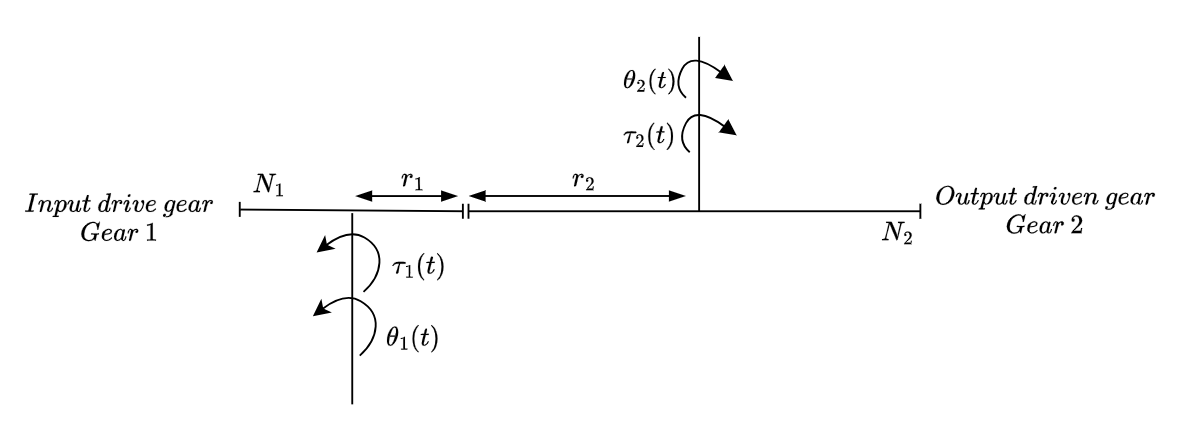

**Figure 4.19: **Gear diagram.

We know that the distance traveled along each gear's circumference is the same. Thus,

$r_1\theta_1(s)=r_2\theta_2(s)$,

which is equivalent to the relationships


$$\frac{\theta_2(s)}{\theta_1(s)}=\frac{r_1}{r_2}=\frac{N_1}{N_2}$$


since the ratio of the number of teeth along the circumference is in the same proportion as the ratio of the radii. We conclude that the ratio of the angular displacement of the gears is inversely proportional to the ratio of the number of teeth.

Based on rotational energy principle:

$T_1\theta_1=T_2\theta_2$.

From this, we can deduce that

$\frac{T_2(s)}{T_1(s)}=\frac{\theta_1(s)}{\theta_2(s)}=\frac{N_2}{N_1}$.

Thus, the torques are directly proportional to the ratio of the number of teeth. The block diagrams indicate the mappings, which depends on whether torque or angular displacement is being considered.

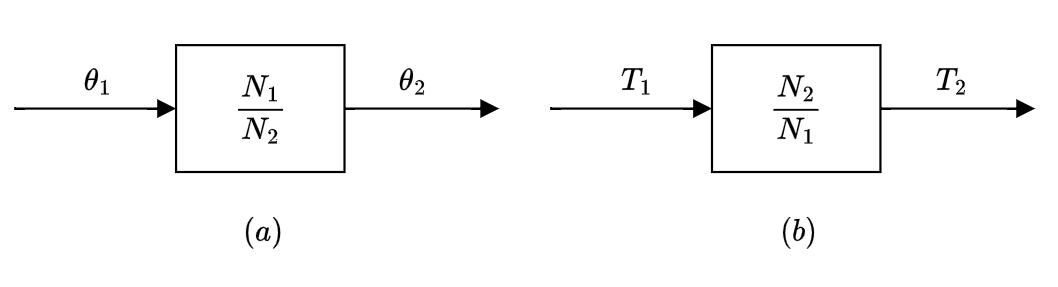

**Figure 4.20: **Block diagram showing input-output mapping of (a) rotational displacement and (b) torque.

We will assume in this course that the gears are *idealised*. That is, the gears have no inertia. 

### 4.6.1 Reflecting impedances and torques across gear trains

Consider the torsional mass-spring-damper system with one stage of gearing.

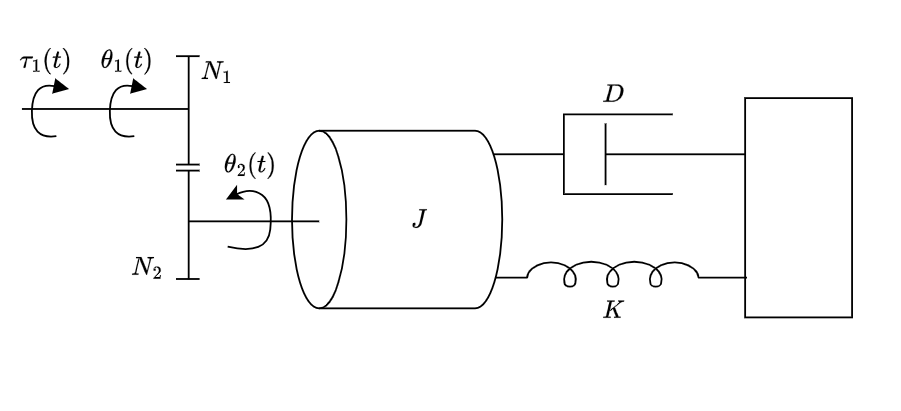

**Figure 4.21: **Torsional mass-spring-damper with one stage of gearing.

Using our understanding of modelling gears, the above system can be represented by either reflecting the applied torque on the input shaft to the output shaft, or we can reflect all impedances from the output shaft to the input shaft.

#### Reflecting to the output shaft

From the previous section, we know that

$T_2(s)=\frac{N_2}{N_1}T_1(s)$.

We can therefore represent output torque, $T_2(s)$, as acting on an equivalent system without gearing, as shown in the figure below. 

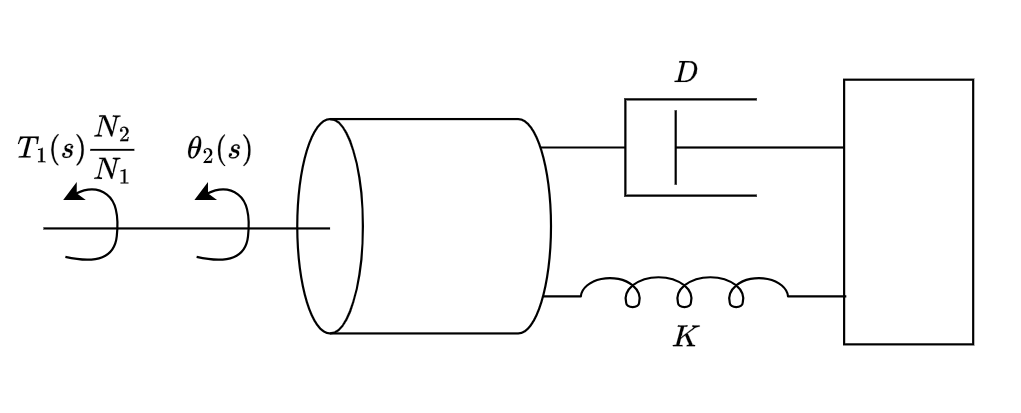

**Figure 4.22: **Equivalent torsional mass-spring-damper with one stage of gearing after reflecting to output shaft.

Using the method of impedances, the torque equation becomes

$\left[ Js^2+Ds+K\right]\theta_2(s)=T_2(s)=T_1(s)\frac{N_2}{N_1}$.

Reflecting to the output shaft is useful when we want to develop a transfer function that relates the applied torque, $T_1(s)$, to the rotational displacement at the output shaft, $\theta_2(s)$. The transfer behaviour follows as

$\frac{\theta_2(s)}{T_1(s)}=\frac{N_2/N_1}{Js^2+Ds+K}$.

#### Reflecting to the input shaft

We can also reflect all information to the input shaft if we are interested in developing a relationship between $T_1(s)$ and $\theta_1(s)$. Considering our torque equation from before of

$\left[ Js^2+Ds+K\right]\theta_2(s)=T_2(s)=T_1(s)\frac{N_2}{N_1}$,

if we substitute $\theta_2(s)=\frac{N_1}{N_2}\theta_1(s)$ and resolve the equation we obtain

$\left(\frac{N_1}{N_2}\right)^2\left[ Js^2+Ds+K\right]\theta_2(s)=T_1(s)$.

Note this is equivalent to reflecting each mechanical impedance from the output shaft to the input shaft, which requires scaling by the square of the output to input gear ratio, $\left(\frac{N_1}{N_2}\right)^2$. The equivalent system at the input is shown below.

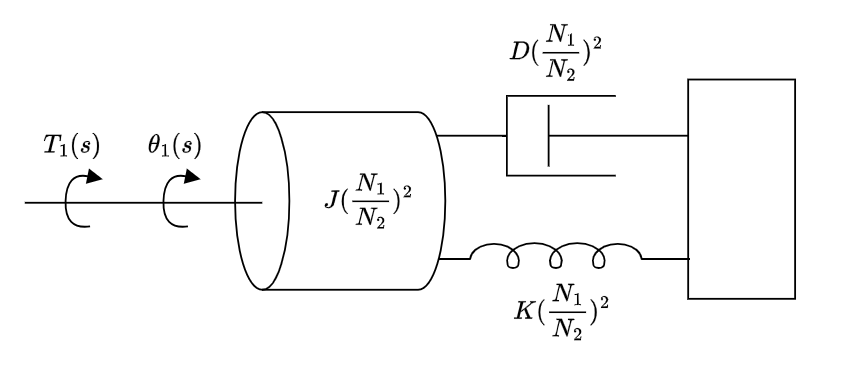

**Figure 4.23: **Equivalent torsional mass-spring-damper with one stage of gearing after reflecting to input shaft.

Generalizing the results of the activity above: Rotational mechanical impedances can be reflected through gear trains by multiplying the mechanical impedance by the ratio

$\left(\frac{\text{Number of teeth of gear on}\textit{ destination} \text{ shaft}}{\text{Number of teeth of gear on} \textit{ source} \text{ shaft}}\right)^2$,

where the impedance to be reflected is attached to the source shaft and is being reflected to the destination shaft. 

#### Example

Determine $\frac{\theta_2(s)}{T_1(s)}$ from the diagram below.

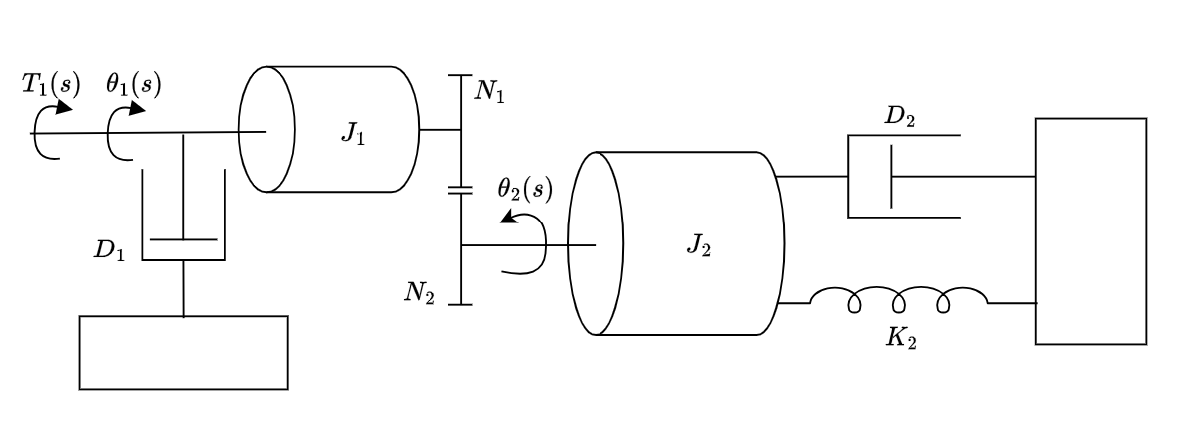

**Figure 4.24: **Example mechanical system

We are interesting in finding the relationship between the input torque, $T_1(s)$, and the output angle, $\theta_2(s)$. Therfore we should reflect all torques and impedances to the output shaft. As before, the torque at the output shaft is 

$T_2(s)=\frac{N_2}{N_1}T_1(s)$.

We also have impedances on the input shaft, namely $J_1$ and $D_1$. We can reflect them to the output shaft by scaling them by $\left(\frac{N_2}{N_1}\right)^2$. Once reflecting all impedances to the output shaft, we can then simply sum common impedances. The equivalent impedances are determined as

$D_e = \left(\frac{N_2}{N_1}\right)^2D_1+D_2$,

$J_e = \left(\frac{N_2}{N_1}\right)^2J_1+J_2$,

$K_e=K_2$,

as shown in the figure below.

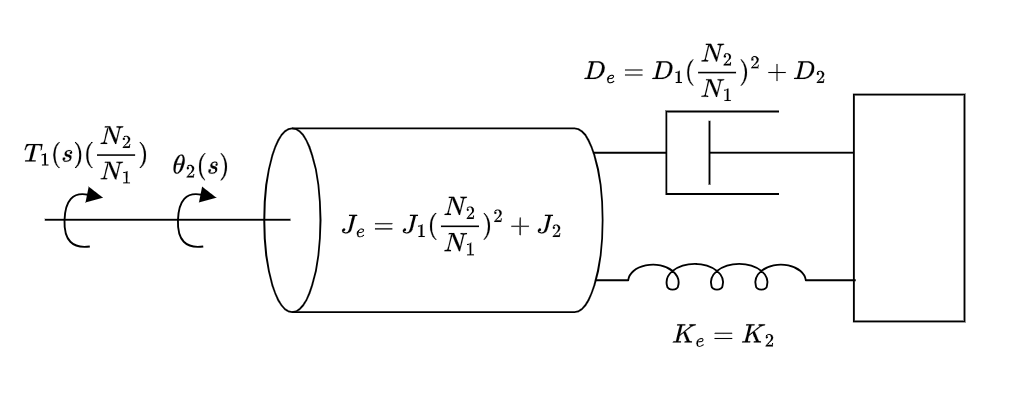

**Figure 4.25: **Example mechanical system after reflecting to output shaft.

The torque equation follows as

$\left[ J_es^2+D_es+K_e\right]\theta_2(s)=T_1(s)\frac{N_2}{N_1}$,

and the resulting transfer function, $\frac{\theta_2(s)}{T_1(s)}$ is determined as

$\frac{\theta_2(s)}{T_1(s)}=\frac{N_2/N_1}{J_es^2+D_es+K_e}$,

as shown below.

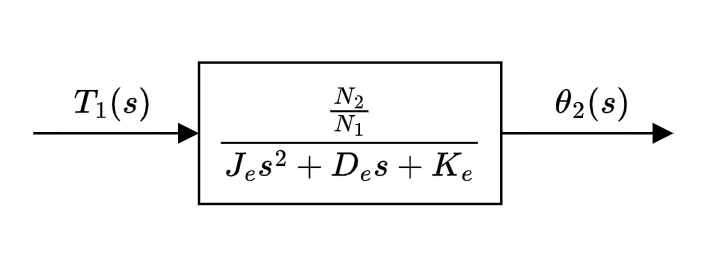

**Figure 4.26: **Block diagram of example mechanical system showing mapping from input torque to output rotational displacement.

### 4.6.2 Gear trains

In order to eliminate gears with large radii, a **gear train** is used to implement large gear ratios by cascading smaller gear ratios. A schematic diagram of a gear train is shown below.

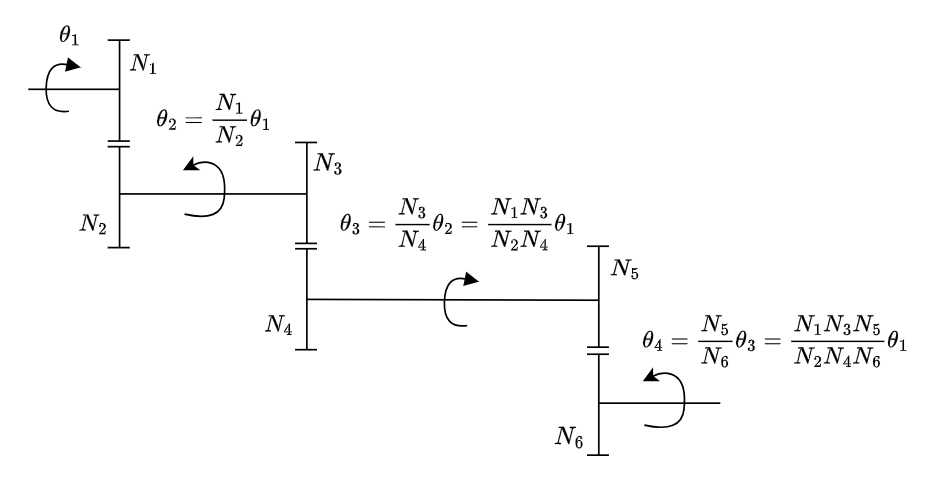

**Figure 4.27: **Idealised gear trains.

For gear trains, we conclude that the equivalent gear ratio is the product of the individual gear ratios. 